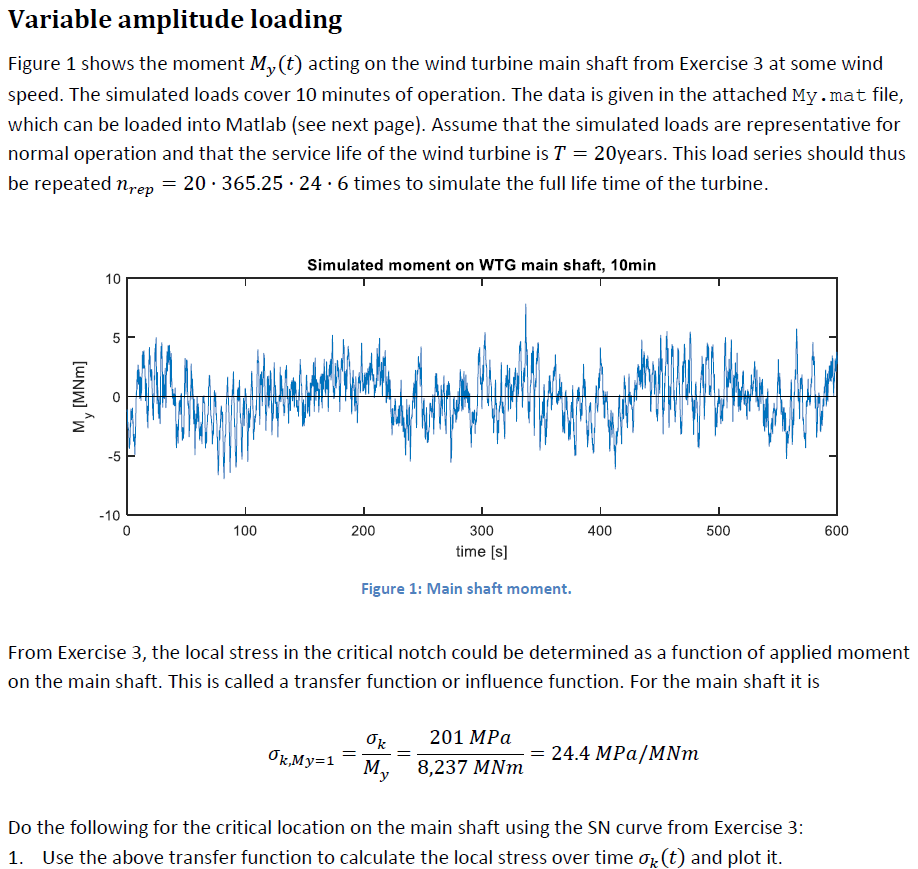

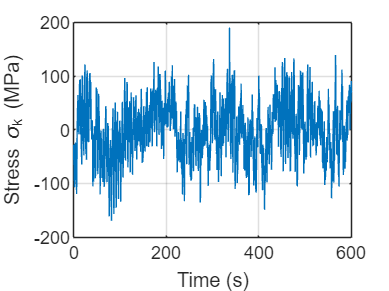

clear all
clf
format longg
load My.mat
% My [MPa]
% t [s]

S_k_my1 = 24.4; % MPa / MNm

S_k = S_k_my1*My;

plot(t,S_k)%, "filled")
xlabel('Time (s)')
ylabel('Stress \sigma_k (MPa)')
grid("on")

[dS, Sm] = rainflow(S_k);
% dS % is the stress range
% Sm % is the associated mean stresses

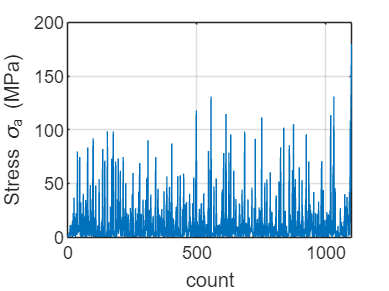

S_a = dS/2;
S_RDk = 154.975228321248;
t_a = linspace(0, length(S_a), length(S_a));
plot(t_a,S_a)%, "filled")
xlabel('count')
ylabel('Stress \sigma_a (MPa)')
grid("on")

dS_max = max(dS)

dS_max =                  360.31785


N_D = 1e6;
m1 = 5;
m2 = 2*m1 - 1

m2 =      9



C1 = S_RDk^m1 * N_D

C1 =       8.93946285800987e+16


C2 = S_RDk^m2 * N_D

C2 =        5.1565657979922e+25



N_a1 = [];
N_a2 = [];
S_a1 = [];
S_a2 = [];
N_max = 1e12

N_max =              1000000000000


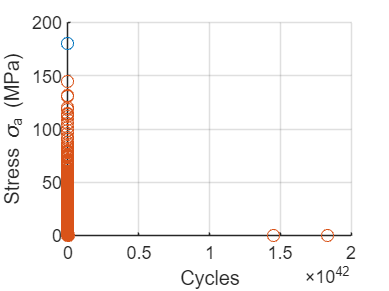

for i = 1:length(S_a)
    if S_a(i) > S_RDk
        N_a1(end +1) = C1 / S_a(i)^m1; %finder et punkt for S_1 med vores maximale lokal spænding
        S_a1(end +1) = S_a(i);
    else
    N_a2_check = C2 / S_a(i)^m2;
        % if  N_a2_check > N_max
            % continue
        % else
            N_a2(end +1) = N_a2_check; %finder et punkt for S_1 med vores maximale lokal spænding
            S_a2(end +1) = S_a(i);
        % end
    end
end

scatter(N_a1,S_a1)%, "filled")
hold on
scatter(N_a2,S_a2)%, "filled")
xlabel('Cycles')
ylabel('Stress \sigma_a (MPa)')
grid("on")
hold off


Ds1 = [];
Ds2 = [];
for i = 1:length(N_a1)
    Ds1(i) = 1/N_a1(i);
end

for i = 1:length(N_a2)
    Ds2(i) = 1/N_a2(i);
end

D_10min = sum(Ds1) + sum(Ds2)

D_10min =       3.72736190612795e-06


year20 = 20 * 365.25 *24 * 6

year20 =      1051920


D_20year = year20 * D_10min

D_20year =           3.92088653629411



% N_a = [];
% for i = 1:length(S_a)
%     if S_a(i) > S_RDk
%         N_a(i) = C1 / S_a(i)^m1; %finder et punkt for S_1 med vores maximale lokal spænding
%     else
%         N_a(i) = C2 / S_a(i)^m2; %finder et punkt for S_1 med vores maximale lokal spænding
%     end
% end
% 
% Ds = [];
% for i = 1:length(S_a)
%     Ds(i) = 1/N_a(i);
% end

% D_10min = sum(Ds)

% D_20year = 20 * 365.25 *24 * 6 * D_10min


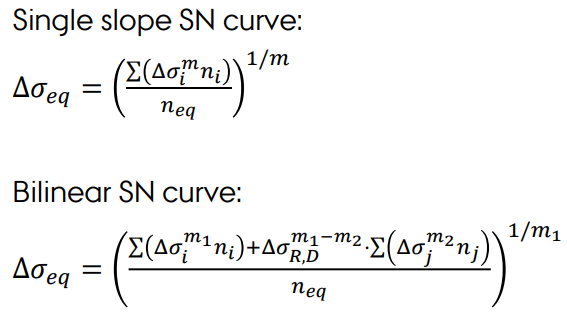

n_i = 1;
n_j = 1;
n_eq = N_D % year20 %

n_eq =      1000000



n_applied = length(S_a) * year20

n_applied =                 1156060080



S_a_eq =  ((sum(S_a1.^m1 .* n_i) + S_RDk^(m1-m2) * sum(S_a2.^m2 .* n_j) ) /...
        n_eq)^(1/m1)

S_a_eq =           12.7216252274375


N_est = n_applied/D_20year;
fprintf('n_applied = %10i\n',n_applied)

n_applied = 1156060080


fprintf('Nest =      %10i cycles\n',round(N_est))

Nest =       294846604 cycles


fprintf('Nest = %10f years\n',20/D_20year)

Nest =   5.100887 years


UR = S_a_eq/((mean(S_a1) + mean(S_a2))/2)

UR =          0.132330926914643


Rm = 400; %MPa 
k_mean = (1-mean(Sm)/Rm)

k_mean =          0.997607206139104


S_RDk

S_RDk =           154.975228321248


S_RDk = 154.975228321248 * k_mean

S_RDk =            154.60440454633
